clearvars; clc;

# Exercitation 3

#### Definitions

s=tf('s');
Gcont=10/(1+s/50);
Ts=0.01;

G=zpk(c2d(Gcont,Ts,'zoh'))


G =
 
    3.9347
  ----------
  (z-0.6065)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



l=2;
l1=0;
l2=2;

#### Disturbance signals

- 
$$\left|y_{\textrm{d2}}^{\infty } \right|\le 0\ldotp 5$$


$\left|y_{\textrm{d2}}^{\infty } \right|=\left|\frac{\delta_2 }{K_l }T^2 \right|$, $K_l =\lim_{z\to 1} {\left(z-1\right)}^l C\left(z\right)G\left(z\right)$

[z_G, p_G, k_G]=zpkdata(G,'v');
B=k_G*[1 -z_G];
A=[1 -p_G(1)];

disp('G(1)='); disp(evalfr(G,1));

G(1)=
    10




$$K_G \ge 0\ldotp 00001$$


2. $\left|y_{\textrm{d1}}^{\infty } \right|\le 0\ldotp 05$

$\left|y_{\textrm{d1}}^{\infty } \right|=\left|\frac{\delta_1 }{K_{\textrm{l2}} }T^2 \right|$, $K_{\textrm{l2}} =\lim_{z\to 1} {\left(z-1\right)}^{\textrm{l2}} C\left(z\right)$


$$K_G \ge 0\ldotp 0001$$


n_add=1; %number of conditions

#### Transient response

s_hat=0.15;
t_s1=0.8;
zeta=abs(log(s_hat))/(sqrt(pi^2+(log(s_hat))^2))

zeta = 0.5169

wn=4.6/(zeta*t_s1);

#### Damping area

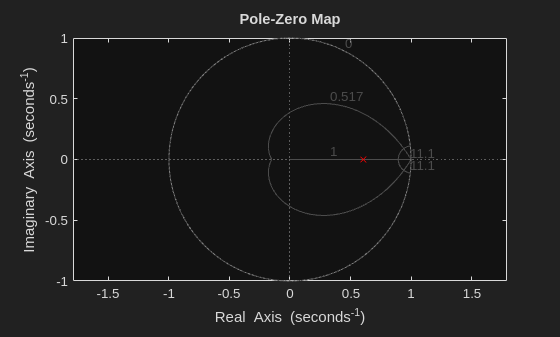

figure;
set(gcf,'Visible','on')
pzplot(G,'r');
axis('equal');
hold on;
zgrid(zeta,wn,Ts);

From the pole-zero map, I can see that I can cancel just one pole (the only pole of G)

#### Zero/Pole cancellation

A_plus=A;
A_minus=1;
B_plus=1;
B_minus=B;

deg_A=1;
deg_B=0;
deg_A_plus=1;
deg_A_minus=0;
deg_B_plus=0;
deb_B_minus=0;
deg_A1=1;

deg_S1=l+deg_A_minus-1+n_add

deg_S1 = 2

deg_R2=deg_A1-deg_B_plus+l1-1+n_add

deg_R2 = 1

deg_Am=l+deg_A_minus+deg_A1-deg_B_plus+l1-1+n_add

deg_Am = 3


A_dioph=conv([1 -1],conv([1 -1],A_minus))

A_dioph =      1    -2     1


B_dioph=B_minus

B_dioph = 3.9347


p1c=-zeta*wn+1i*wn*sqrt(1-zeta^2);
p1=exp(p1c*Ts);
p2=conj(p1);
p3c=-5*wn*zeta;
p3=exp(p3c*Ts);
Am=poly([p1 p2 p3]);
Gamma=[Am';0];
extra_eq=[20*1*Ts^2*ones(1,2) -polyval(A_plus,1)*ones(1,3)]

extra_eq =     0.0020    0.0020   -0.3935   -0.3935   -0.3935



M_s=[[A_dioph';0] [0;A_dioph'] [0;B_dioph';0;0] [0;0;B_dioph;0] [0;0;0;B_dioph]; extra_eq];
theta=M_s\Gamma;

R_2=theta(1:2,:)';
R=conv([1 -1],conv([1 -1],conv(B_plus,R_2)));
S_1=theta(3:5,:)';
S=conv(A_plus,S_1);

C=zpk(tf(S,R,Ts))


C =
 
  0.057007 (z-0.6065) (z^2 - 1.814z + 0.8269)
  -------------------------------------------
              (z-1)^2 (z-0.8541)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.


#### Simulation

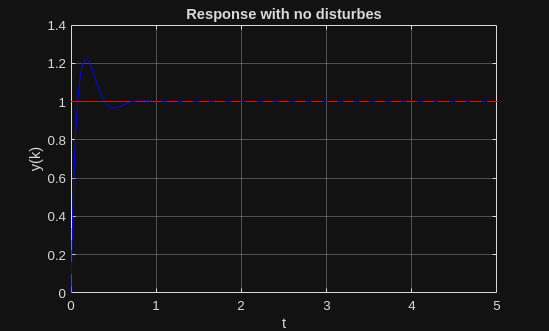

t_sim=5;

r=1;
delta_d1=0;
delta_d2=0;

simout=sim('sim_esercitazione_3');

y=simout.y;

figure, plot(y.time,y.data,'b',y.time,r*ones(y.Length,1),'--r'),
grid on,xlabel('t'),ylabel('y(k)'),title('Response with no disturbes');

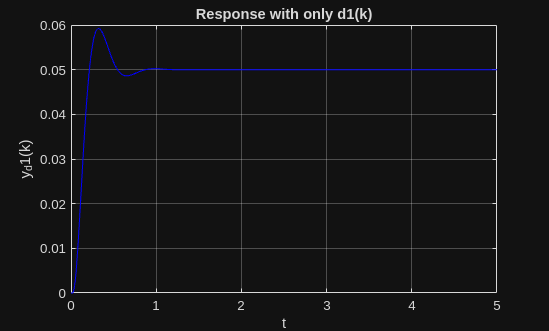


clear simout

r=0;
delta_d1=1;
delta_d2=0;

simout=sim('sim_esercitazione_3');

y_d1=simout.y;

figure, plot(y_d1.time,y_d1.data,'b'),
grid on,xlabel('t'),ylabel('y_d1(k)'),title('Response with only d1(k)');

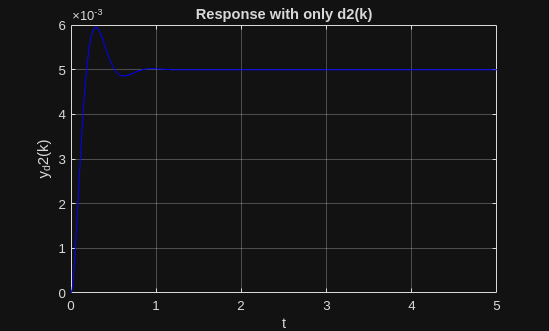


clear simout

r=0;
delta_d1=0;
delta_d2=1;

simout=sim('sim_esercitazione_3');

y_d2=simout.y;

figure, plot(y_d2.time,y_d2.data,'b'),
grid on,xlabel('t'),ylabel('y_d2(k)'),title('Response with only d2(k)');